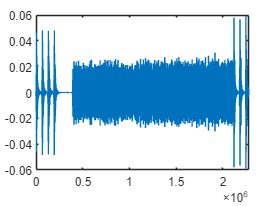

K = 2048;
L = 200;
Fc = 24000;
B = 8000;
W = 24;
Lambda = 24;
Sampler = 256000;
vel = 1.03;
c = 1500;
%a = vel/c;

%%% Step 1: PB filter to remove noise beyond PB
y_in = rece_data_ofdm_bench; %load benchmark_rece_data_174623_1472.mat
%ypb = zeros(length(y_in), 1);
ypb = bandpass(y_in, [-1000+Fc, 8000+Fc], Sampler);
plot(ypb);


%%% Step 2: Estimate a
Ttx = 8269.52; %In ms
Ttxs = Ttx / 1000; %In sec
sr = 1 / Sampler; %Sampling rate in seconds
Trxest = 2117460 * sr; %Estimated Trx duration in sec
a = Ttxs/Trxest-1 % The minus 1 was missing before

a = -2.1860e-04

a_est = a_est_174623 %TA's given a_hat value, load benchmark_parameter_174623_1472.mat

a_est = 5.0000e-05

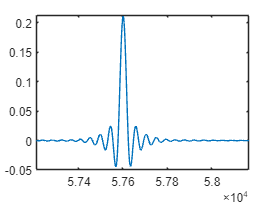

%%% Step 3: Resampling
ypb_re = resample(ypb, round((1+a)*1*exp(5)), round(1*exp(5))); %%% Double check with TA
ypb_re_est = resample(ypb, round((1+a_est)*1*exp(5)), round(1*exp(5)));
%%% Step 4: Resampling from 256k to 192k
Ls = 192;
Ms = 256;
Lp = 24;
N = Lp*Ls-1;
h = Ls*fir1(N, 1/Ms, kaiser(N+1, 7.8562));
Ytildapb_re = upfirdn(ypb_re, h, Ls, Ms);
Ytildapb_re_est = upfirdn(ypb_re_est, h, Ls, Ms);
%plot(Ytildapb_re);
%freqz(Ytildapb_re, 1);

%%% Step 5: Synchronization
pilotpb = OFDM_data_pre_old; %load pilot_signal_for_syncronizaation.mat
%plot(pilotpb);

correlate = xcorr(Ytildapb_re, pilotpb); % Our a_hat value
%plot(correlate)

correlate_est = xcorr(Ytildapb_re_est, pilotpb); % TA's a_hat value
%plot(correlate_est)

n_0 = 2004300 - length(Ytildapb_re_est);



% test = find(round(correlate)~=0);
% newcorr=correlate(test(1):end)
% plot(newcorr)

new_Ytildapb_re_est = Ytildapb_re_est(n_0:end);
%plot(new_Ytildapb_re_est)

%%% Step 6 Convolvlution for PB -> BB

new_part2_Ytildapb_re_est = conv(new_Ytildapb_re_est, h_comp); % Convolution
%plot(new_part2_Ytildapb_re_est)
new_part3_Ytildapb_re_est = new_part2_Ytildapb_re_est(51:end);

%%% Step 7 PB -> BB
for n = 1:length(new_part3_Ytildapb_re_est)
Y_BB_I(n) = new_part3_Ytildapb_re_est(n)*2*cos(2*pi*Fc*n*1/Sampler);
end

for n = 1:length(new_part3_Ytildapb_re_est)
Y_BB_Q(n) = -new_part3_Ytildapb_re_est(n)*2*sin(2*pi*Fc*n*1/Sampler);
end

for n = 1:length(new_part3_Ytildapb_re_est)
Y_BB(n) = Y_BB_I(n) + 1i*Y_BB_Q(n);
end

%plot(Y_BB)

%%% Step 8 Raised Cosine Convolution
beta = .125; % roll-off factor
Fs = 192000; % sampling frequency
Fd = 8000; % data/transfer rate
lamda_oversamp = Fs/Fd;
delay = 100;
span = 2*delay*lamda_oversamp;
Rn = rcosdesign(beta, span, Fs/Fd, 'sqrt');
plot(Rn)

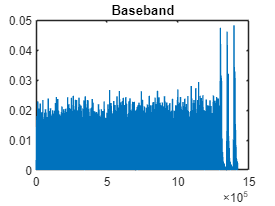

D = 2*delay*lamda_oversamp;
plot(abs(Y_BB))
title("Baseband");

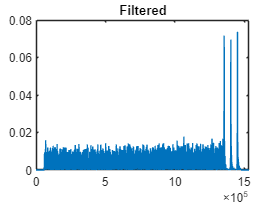

Y_BB_filtered = conv(Y_BB, Rn); % Same as part 1 Step 5
plot(abs(Y_BB_filtered))
title("Filtered");

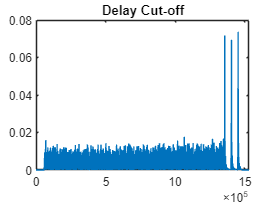

%plot(real(fft(Y_BB)))
Y2 = Y_BB_filtered(1:length(Y_BB_filtered)-D);
plot(abs(Y2))
title("Delay Cut-off");

%%% Step 9
